# Analysis of the Simulation Data from Saddle-Node Bifurcation

clearvars;
addpath(genpath('../'))

## Generating simulation data

rng(1)
%{
lambda_0 = -3;
x_0 = 2.1038;
par.T_max = 6;
par.dt = 1e-5;
sigma = 40;
[x_out, t_out, lambda_out] = generating_simulation_data_sn (@V_potential, sigma, x_0, lambda_0, par);
figure;
plot(t_out,x_out)


sample_id = abs(t_out-3.257)<0.02;
x_out_sample = x_out(sample_id);
t_out_sample = t_out(sample_id);

figure;
plot(t_out_sample,x_out_sample)

N_cell = length(x_out_sample);
sub_sample_id = 1:2:N_cell;
N_cell = length(sub_sample_id);
data = x_out_sample(sub_sample_id )';
true_labs = t_out_sample (sub_sample_id );


%save 

save('../Data/saddlenode_new.mat','x_out_sample','t_out_sample','sample_id','x_out','t_out','lambda_out','sigma','data');
%}

## Load the Data and Estimate Number of Clusters by EPI

From EPI plot, we intend to seek for the index where peak occurs, which serves as the candidate for the choice of cluster numbers

load saddlenode.mat
out = EstClusterNum(data,[]);

Computed P-values 500 of 2000 datapoints...
Computed P-values 1000 of 2000 datapoints...
Computed P-values 1500 of 2000 datapoints...
Computed P-values 2000 of 2000 datapoints...
Mean value of sigma: 0.62417
Minimum value of sigma: 0.54639
Maximum value of sigma: 0.75299


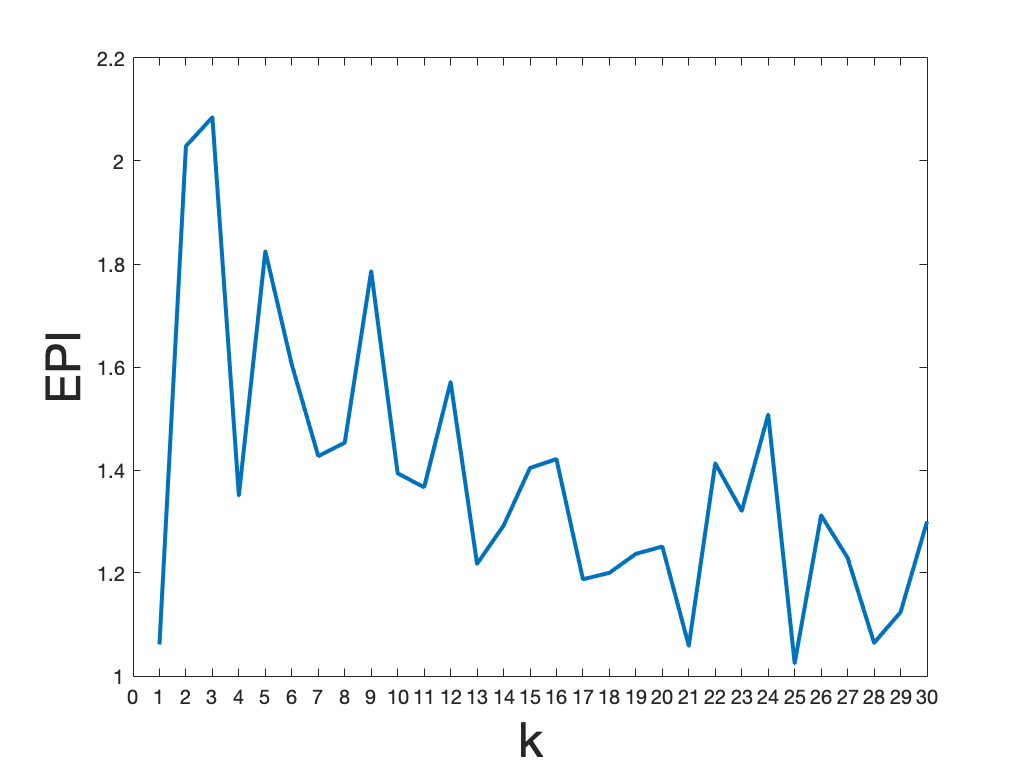

plot(out.ratio(1:30), 'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);
xticks(0:30);

## Dynamical Analysis and Output

tic;
par.choice_distance = 'euclid';
par.K_cluster = 2; %selected based on EPI
par.trials = 20; % number of random trails in MuTrans, increase this to guaratee more robustness
% the main function of MuTrans
Output = DynamicalAnalysis (data, par);

Computed P-values 500 of 2000 datapoints...
Computed P-values 1000 of 2000 datapoints...
Computed P-values 1500 of 2000 datapoints...
Computed P-values 2000 of 2000 datapoints...
Mean value of sigma: 0.62417
Minimum value of sigma: 0.54639
Maximum value of sigma: 0.75299


J_new = 2.0186

J_new = 1.9458

J_new = 1.7978

J_new = 1.2289

J_new = 1.2248

J_new = 1.2228

J_new = 1.2227

J_new = 1.2227

J_new = 1.2726

J_new = 1.2064

J_new = 1.2029

J_new = 1.2022

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.2039

J_new = 1.2013

J_new = 1.2012

J_new = 1.2012

J_new = 1.9314

J_new = 1.3082

J_new = 1.2736

J_new = 1.2414

J_new = 1.2271

J_new = 1.2238

J_new = 1.2228

J_new = 1.2227

J_new = 1.2227

J_new = 1.7034

J_new = 1.5456

J_new = 1.3847

J_new = 1.2039

J_new = 1.2013

J_new = 1.2012

J_new = 1.2012

J_new = 2.0398

J_new = 1.9975

J_new = 1.9374

J_new = 1.8711

J_new = 1.8338

J_new = 1.7806

J_new = 1.7073

J_new = 1.6795

J_new = 1.6351

J_new = 1.5776

J_new = 1.4679

J_new = 1.2018

J_new = 1.2013

J_new = 1.2012

J_new = 1.2012

J_new = 1.7439

J_new = 1.2251

J_new = 1.2064

J_new = 1.2029

J_new = 1.2022

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.4074

J_new = 1.2198

J_new = 1.2118

J_new = 1.2047

J_new = 1.2022

J_new = 1.2012

J_new = 1.2012

J_new = 1.2566

J_new = 1.2138

J_new = 1.2031

J_new = 1.2022

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.9787

J_new = 1.9039

J_new = 1.8986

J_new = 1.8913

J_new = 1.8793

J_new = 1.8363

J_new = 1.6907

J_new = 1.6654

J_new = 1.6276

J_new = 1.5695

J_new = 1.4416

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.4496

J_new = 1.2050

J_new = 1.2024

J_new = 1.2016

J_new = 1.2012

J_new = 1.2012

J_new = 1.9824

J_new = 1.9375

J_new = 1.9336

J_new = 1.9305

J_new = 1.9276

J_new = 1.9196

J_new = 1.9075

J_new = 1.8997

J_new = 1.8934

J_new = 1.8835

J_new = 1.8584

J_new = 1.6937

J_new = 1.6728

J_new = 1.6341

J_new = 1.5790

J_new = 1.4702

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.6831

J_new = 1.2031

J_new = 1.2022

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.2270

J_new = 1.2235

J_new = 1.2227

J_new = 1.2227

J_new = 1.7183

J_new = 1.2072

J_new = 1.2031

J_new = 1.2022

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.2220

J_new = 1.2057

J_new = 1.2024

J_new = 1.2016

J_new = 1.2012

J_new = 1.2012

J_new = 1.9753

J_new = 1.9521

J_new = 1.9035

J_new = 1.8986

J_new = 1.8833

J_new = 1.8606

J_new = 1.8512

J_new = 1.8470

J_new = 1.8458

J_new = 1.8448

J_new = 1.8441

J_new = 1.8414

J_new = 1.8297

J_new = 1.7931

J_new = 1.6386

J_new = 1.2334

J_new = 1.2262

J_new = 1.2235

J_new = 1.2227

J_new = 1.2227

J_new = 1.7555

J_new = 1.2307

J_new = 1.2275

J_new = 1.2241

J_new = 1.2234

J_new = 1.2209

J_new = 1.2157

J_new = 1.2083

J_new = 1.2039

J_new = 1.2013

J_new = 1.2012

J_new = 1.2012

J_new = 1.2070

J_new = 1.2026

J_new = 1.2021

J_new = 1.2014

J_new = 1.2012

J_new = 1.2012

J_new = 1.2866

J_new = 1.2247

J_new = 1.2232

J_new = 1.2227

J_new = 1.2227

J_new = 1.2227

E_best = 0.0375

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          1.20181                      1.83e-05
     1          11          1.17728         168199        0.00031  
     2          13          1.17708            0.1       0.000334  
     3          14          1.17143              1        0.00031  
     4          15          1.16935              1       0.000237  
     5          16          1.16811              1       0.000192  
     6          17          1.16574              1       0.000122  
     7          18          1.16484              1       0.000138  
     8          19          1.16393              1       6.32e-05  
     9          20          1.16347              1       6.29e-05  
    10          21          1.16293              1       0.000139  
    11          22          1.16238              1       0.000276  
    12          23          1.16147              

toc;

Elapsed time is 77.917476 seconds.



class_order = Output.class_order;
rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_perm = Output.P_perm;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
P_rho = Output.P_rho;
labs_perm = Output.labs_perm;
data_perm = Output.data_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;

Plot the Cell-Cell Scale rwTPM

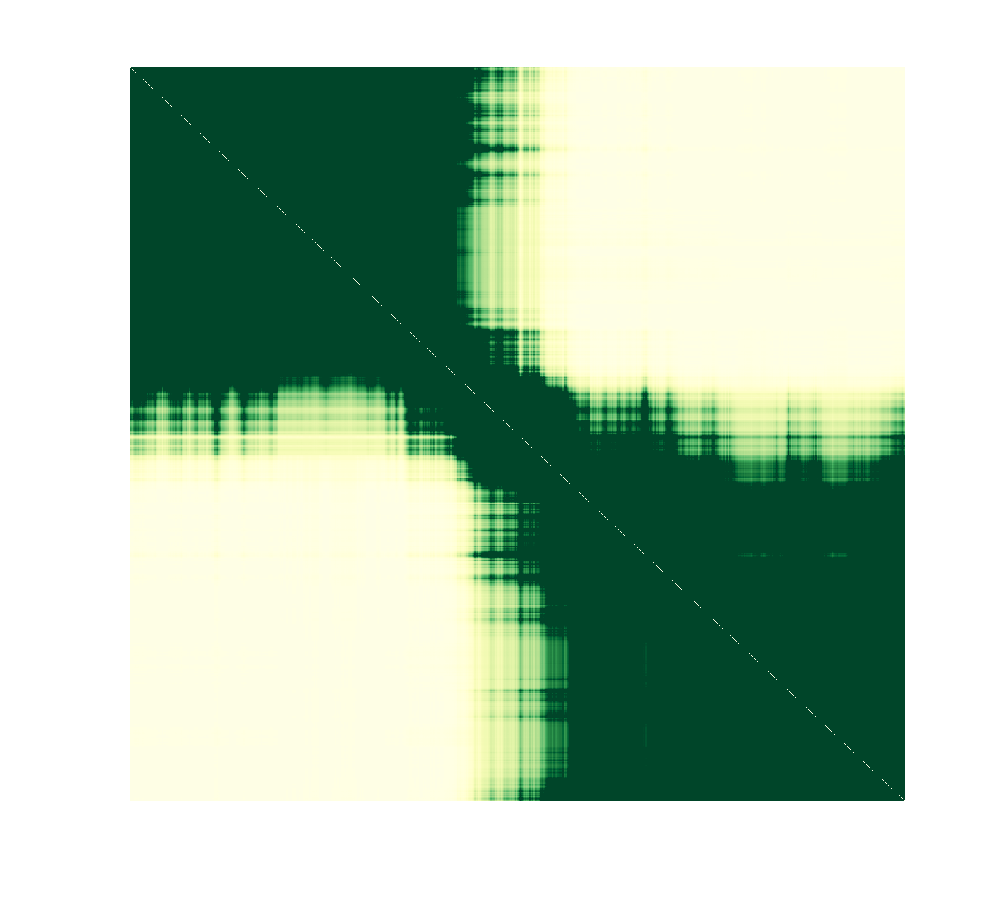

max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

%colorbar;

Plot the Cluster-Cluster Scale rwTPM

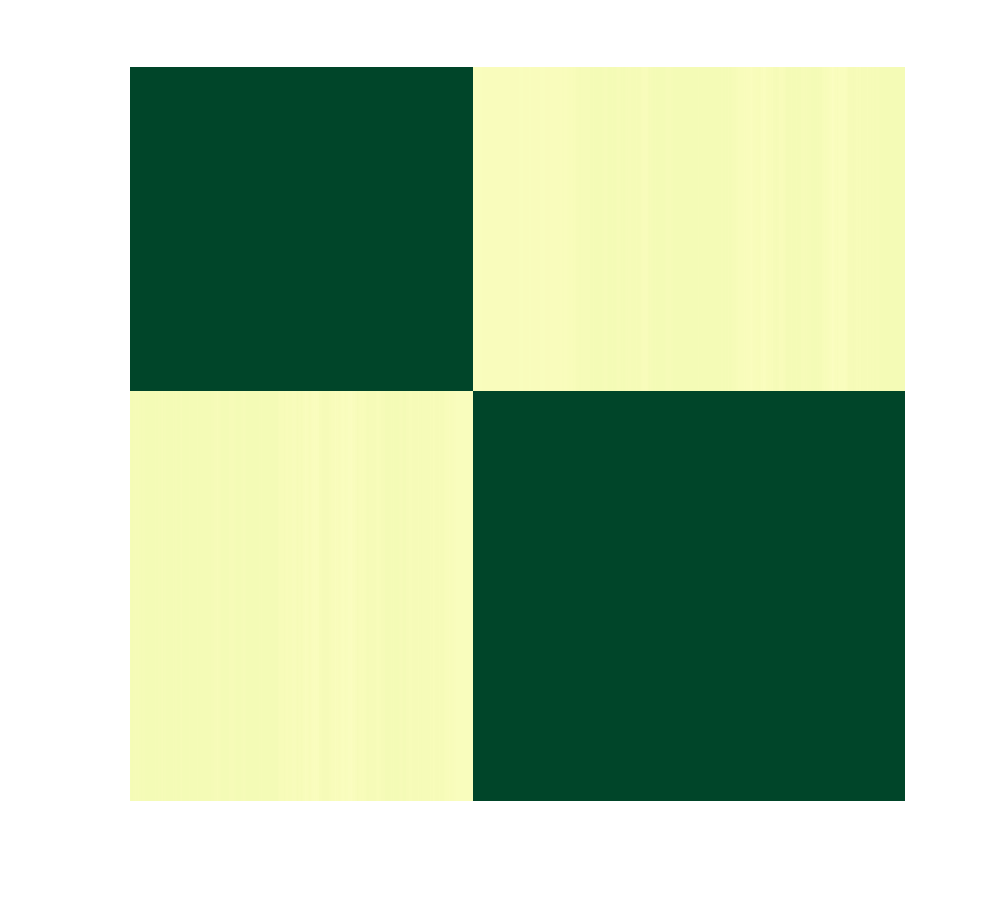

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

%colorbar;


Plot the Cell-Cluster Scale rwTPM

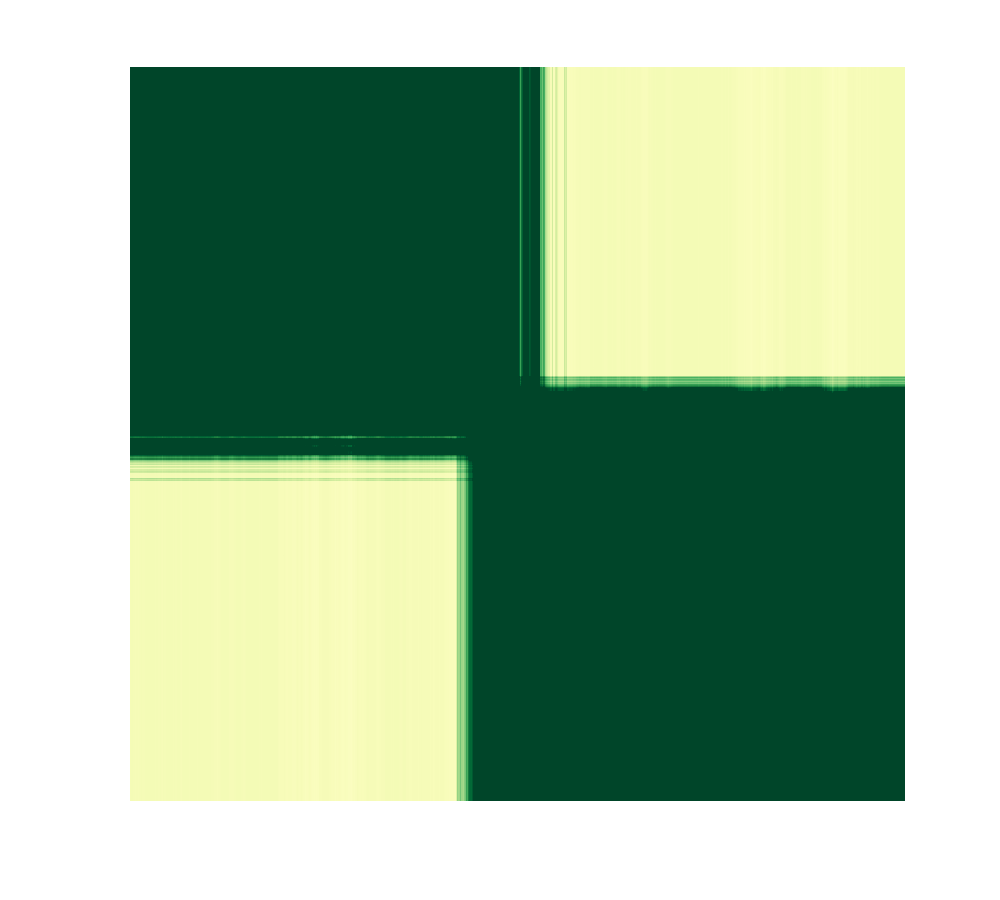


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

Plot Transition Cell Score (TCS)

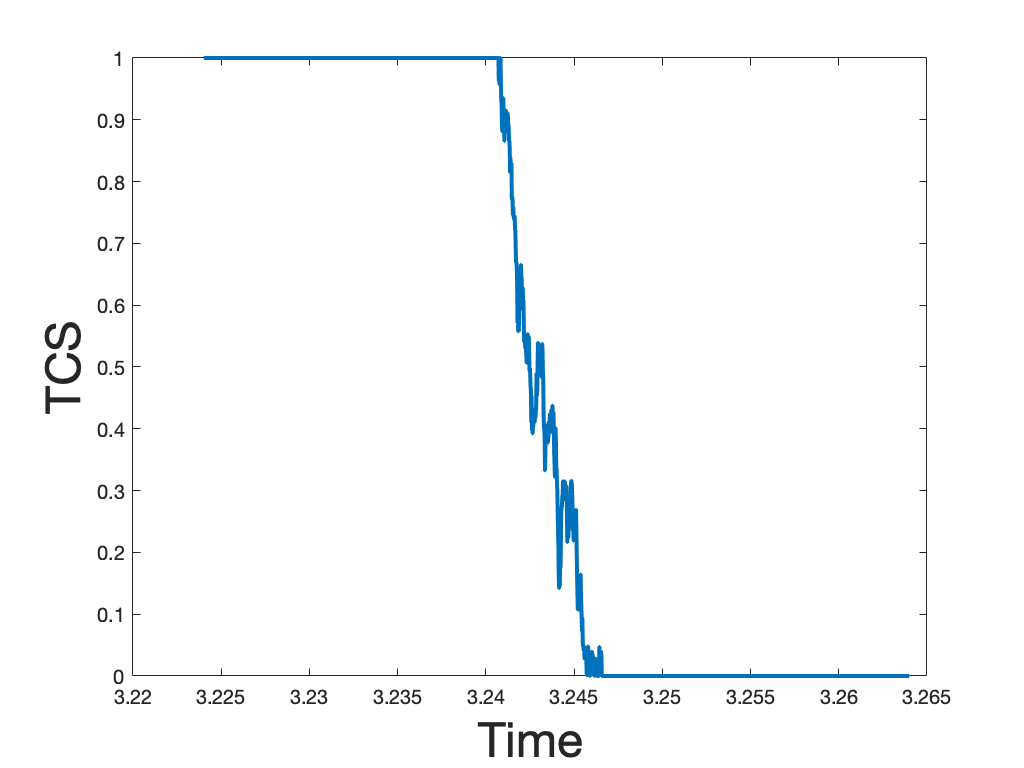

figure;
plot(labs_perm, rho_class(:,1),'LineWidth',2)
xlabel('Time', 'FontSize', 24);
ylabel('TCS', 'FontSize', 24);

Plot Actual Simulation Trajectory (Gene Expression)

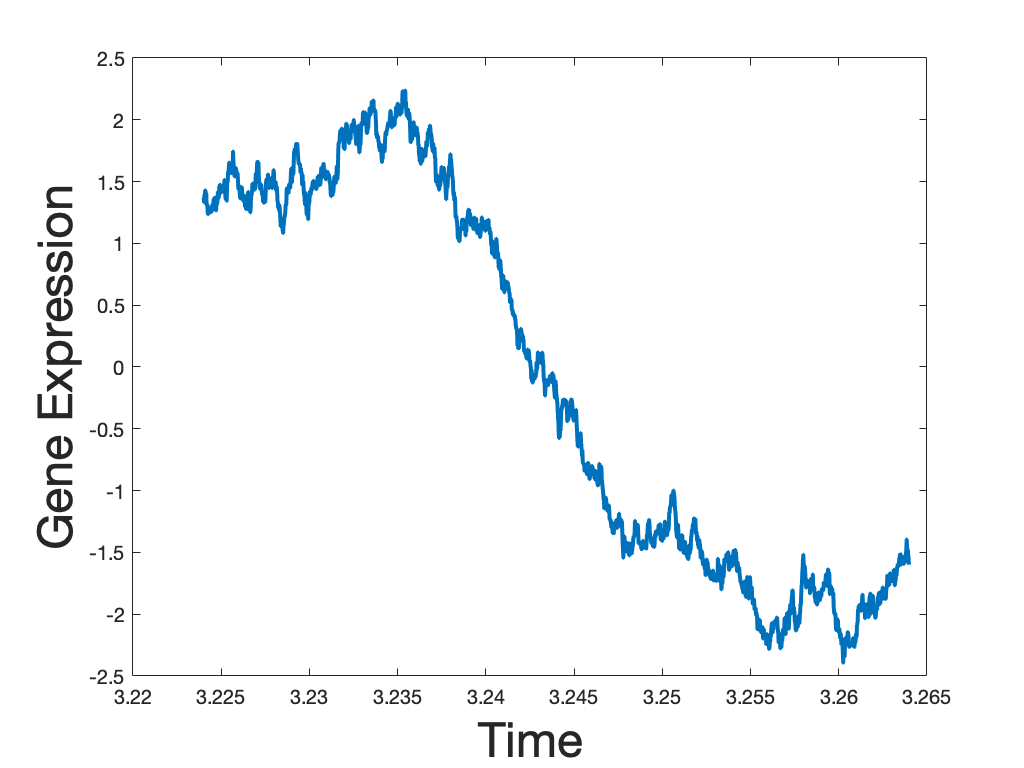

figure;
plot(labs_perm, data_perm,'LineWidth',2)
xlabel('Time', 'FontSize', 24);
ylabel('Gene Expression', 'FontSize', 24);